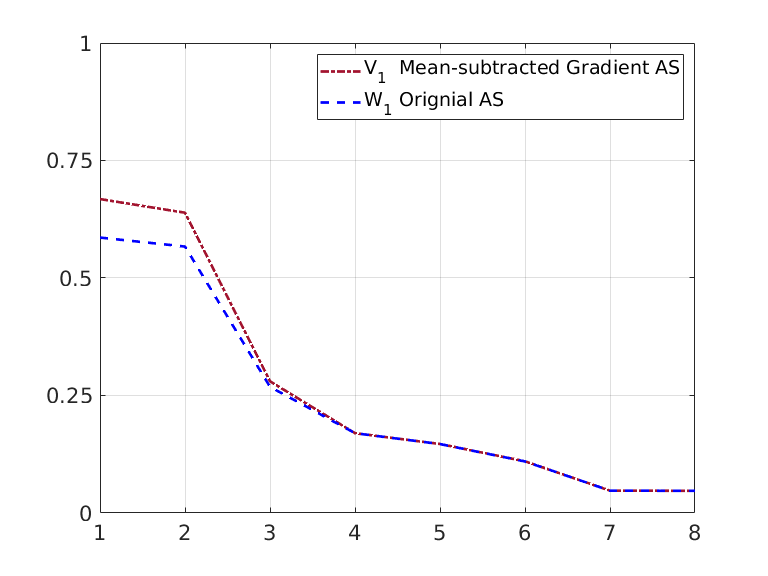

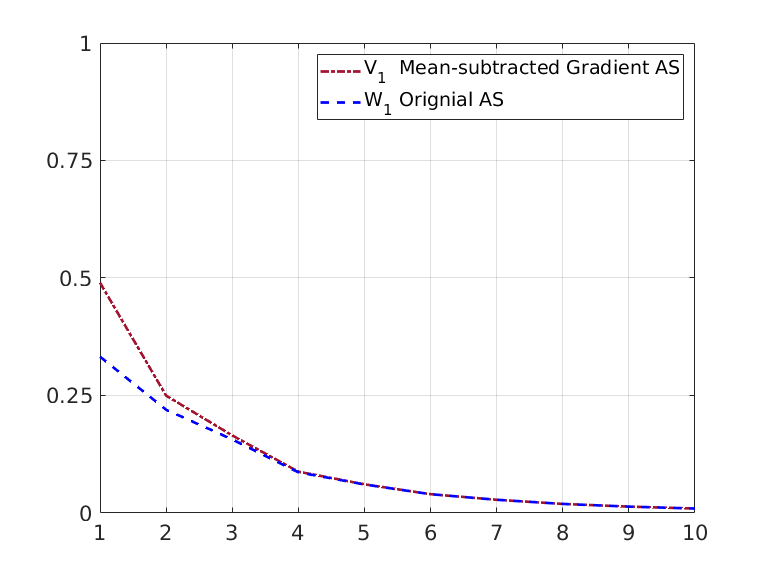

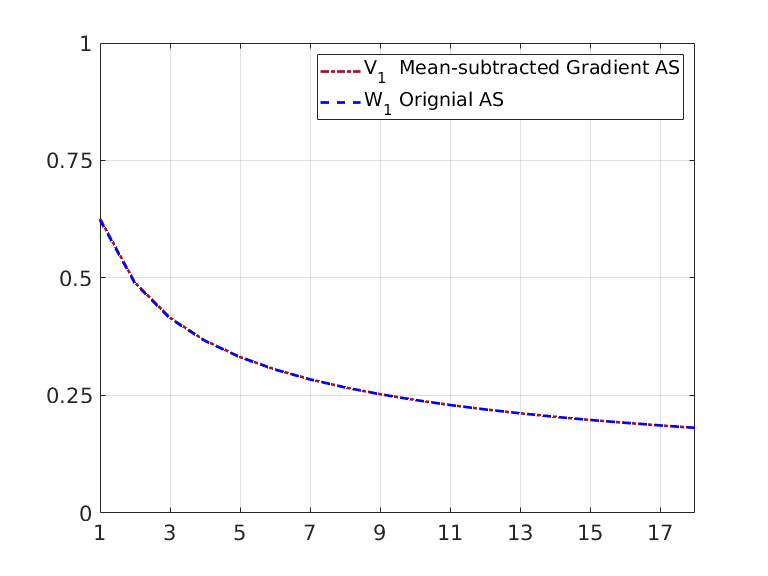

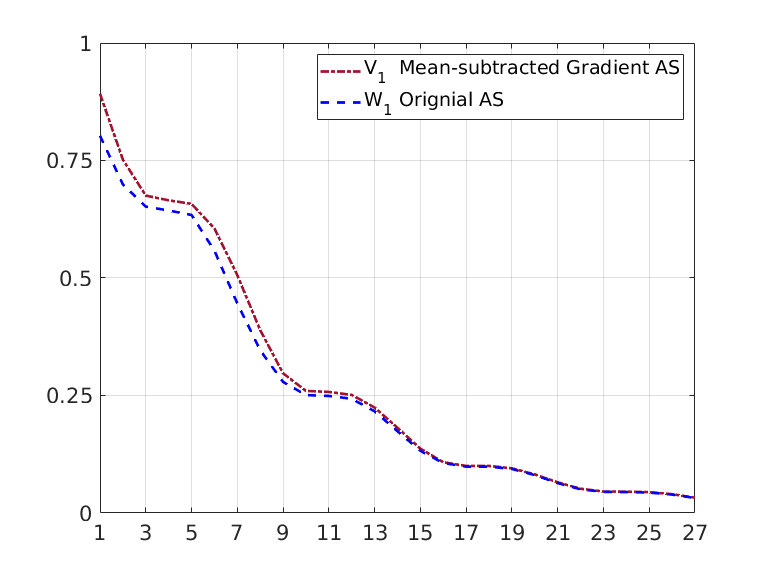

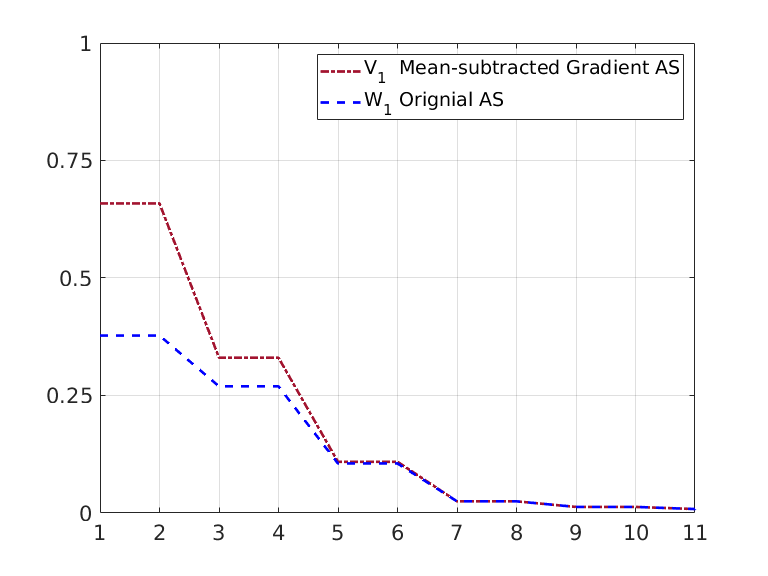

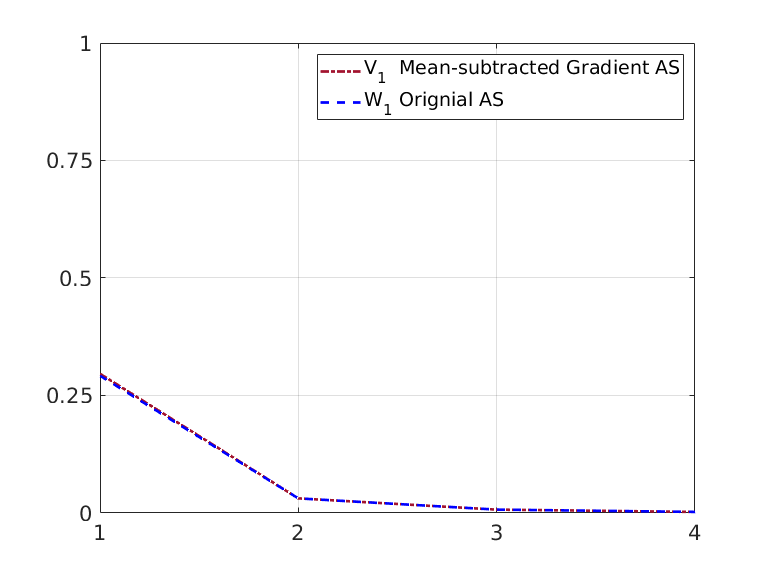

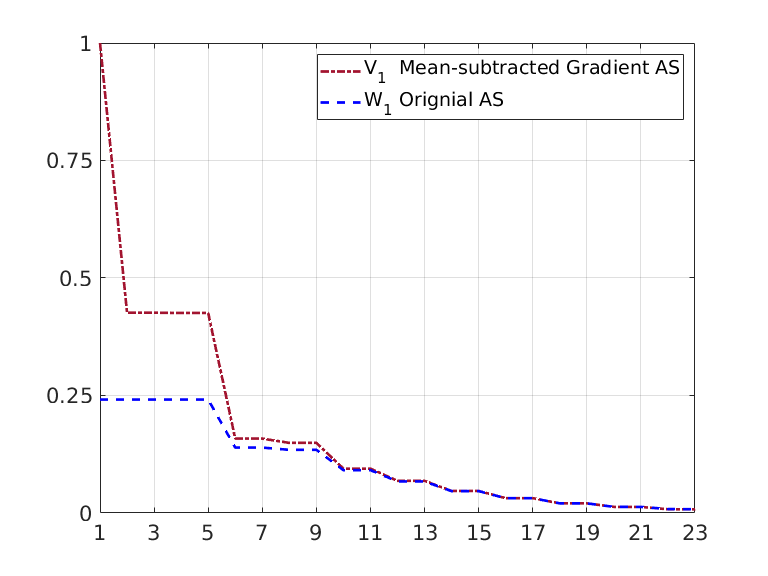

clear all; clc; close all;

for problem = 1:7
    %     rand('state',20);
    %     randn('state',18);

    n = 1000; % number of grid points
    noise = 1; % noise level is 5% for all problem
    s = linspace(0,1,n); % x axis
    sp = floor(n/10);% for plot markers


    if problem == 1
        [A,y0,xtrue] = shaw(n); name = '1D_Shaw';
        Position = 'northwest';
        position_error = 'north'; y_err_max = 100;
        ymax = 2.5;         ymin = -0.5;
    elseif problem == 2
        [A,y0,xtrue] = gravity(n); name = '1D_Gravity';
        Position = 'northeast';
        position_error = 'northeast'; y_err_max = 100;
        ymax = 1.5;         ymin = -0.2;
        ytickk = [-0.2 0 0.5 1 1.5];
    elseif problem == 3
        [A,y0,xtrue] = deriv2(n); name = '1D_Deriv2';
        Position = 'northwest';
        position_error = 'northeast'; y_err_max = 100;
        ymax = .05;         ymin = -0.01;
    elseif problem == 4
        [A,y0,xtrue] = heat(n); name = '1D_Heat';
        Position = 'northeast';
        position_error = 'northeast'; y_err_max = 100;
        ymax = 1.05;         ymin = -0.05;
    elseif problem == 5
        [A,y0,xtrue] = phillips(n); name = '1D_Phillips';
        Position = 'northeast';
        position_error = 'northeast'; y_err_max = 100;
        ymax = 0.25;         ymin = -0.05;
    elseif problem == 6
        [A,y0,xtrue] = foxgood(n); name = '1D_Foxgood';
        Position = 'northwest';
        position_error = 'northwest'; y_err_max = 100;
        ymax = 1.2;         ymin = 0;
    elseif 7
        n = 1000; sp = floor(n/10);
        s = linspace(0,1,n+1)'; t = s;

        % Discretize the deblurring kernel
        beta = 0.05;
        a = 1/sqrt(2*pi*beta^2)*exp(-0.5*(1/beta^2)*t.^2);
        A = 1/n*toeplitz(a);

        % Truth
        xtrue = 10*(t-0.5).*exp(-0.5*1e2*(t-0.5).^2) -0.8 + 1.6*t;

        % ------------additive noise-----------
        noise = 5;       % Noise level in percentages of the max. of noiseless signal
        y0 = A*xtrue;    % Noiseless signal

        name = '1D_Decon';
        Position = 'southeast';
        position_error = 'northeast'; y_err_max = 100;
        ymax = 1;         ymin = -1;
        xtic = [1 2 5 6 10 15 20];

    end

    r_optimal = [7,7,15,22,8,3, 16];
    r_add =[1,3,3,5,3,1,7];

    r = r_optimal(problem) + r_add(problem);

    % y0 = A*xtrue; % for more accurate
    STD_noise = max(abs(y0))*noise/100;
    y_obs = y0 + STD_noise*randn(size(y0));
    y_obs_bar = y_obs; A_bar = A;
    
%     d = size(y_obs,1); p = size(xtrue,1);
%     % Data covariance
%     sigma_square = STD_noise^2;
%     SIGMA_SqR =  STD_noise * eye(d);
%     SIGMA_SqR_INV = 1/STD_noise * eye(d);

## Active subspace matrices

    C = A_bar' * (A_bar*A_bar' + y_obs_bar*y_obs_bar') * A_bar;
    [W,S_ddT,W] = svd(C);
    C = A_bar' * (A_bar*A_bar') * A_bar;
    [V,S_ddT,V] = svd(C);
    
%     [U,S,V] = svd(A_bar' * (A_bar*A_bar') * A_bar);


## PLot results

    UT_d = V'*xtrue;
    WT_d = W'*xtrue;

% 
%     figure('Units','normalized','Position',[0 0 0.15 0.4], 'PaperPositionMode', 'auto'); hold on
%     set(gca,'FontSize', 16, 'fontname', 'Times New Roman' )
%     hold on
%     scatter(1:r,UT_d(1:r),100,'Marker','d','MarkerEdgeColor',[0.6350 0.0780 0.1840],'Linewidth',2,'DisplayName','V_1 Mean-subtracted Gradient AS')
% 
%     scatter(1:r,WT_d(1:r),100,'Marker','o','MarkerEdgeColor','b','Linewidth',2,'DisplayName','W_1 Original AS')
%     xlim([1 r])
% 
%     % xlabel('Active subspace direction indices')
%     % ylabel('Coefficients   d_i = (d,\cdot)')
%     legend
%     xticks([1:r])
%     grid on
%     box on
    
    for i = 1:r
        d_i = V(:,1:i) * UT_d(1:i);
        Energy_V(i) = norm(xtrue - d_i) / norm(xtrue) ;

        d_i = W(:,1:i) * WT_d(1:i);
        Energy_W(i) = norm(xtrue - d_i) / norm(xtrue) ;
    end


    figure('Units','normalized','Position',[0 0 0.15 0.4], 'PaperPositionMode', 'auto'); hold on
    set(gca,'FontSize', 16, 'fontname', 'Times New Roman' )
    %     set(gca, 'YScale', 'log')
    hold on
    loglog(Energy_V,'Color',[0.6350 0.0780 0.1840],'Linestyle','-.','Linewidth',2,'DisplayName','V_1  Mean-subtracted Gradient AS');
    loglog(Energy_W,'Color','b','Linestyle','--','Linewidth',2,'DisplayName','W_1 Orignial AS');
    %     xlabel('Rank of active subspace')
    %     ylabel('||d - d_{r} ||_2 / ||d||_2')
    if problem == 7 || problem == 3 || problem == 4
        xticks(1:2:r)
    else
        xticks((1:r))
    end
    yticks([0.0 .25 .5 .75 1])
    axis([1 r 0 1]);
    legend('Location','northeast')
    box on
    grid on

    saveas(gcf,[name '_error_Projection'],'epsc')


end